clc
clear all

## Reading run file

run = readtable("Diego_13_09_2023_AM_2.csv");
run = run(1:480,:);

speed = table2array(run(:,6));
power = table2array(run(:,7));
cadence = table2array(run(:,4));
hrate = table2array(run(:,3));
dist = table2array(run(:,5));
time = 1:size(hrate);
h = table2array(run(:,"altitude"))/10;

## Plotting run 

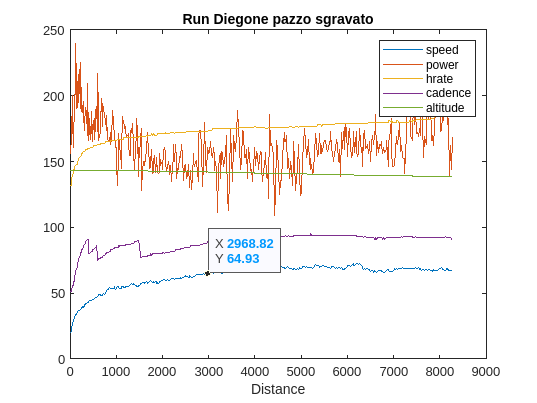

plot(dist,speed,dist,power,dist,hrate,dist,cadence,dist,h);
legend("speed","power","hrate","cadence","altitude");
title("Run Diegone pazzo sgravato");
xlabel("Distance");

## Fitting speed curve

a = -190.0034;
b = -0.0869;
c = 158.2421;
speed_fitted = a.*dist.^b+c;

## System modeling

sys = [speed_fitted,power];
nx = 1;
model = n4sid(sys,nx)

model =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
           x1
   x1  0.9885
 
  B = 
               u1
   x1  -1.689e-05
 
  C = 
           x1
   y1  -299.1
 
  D = 
       u1
   y1   0
 
  K = 
              y1
   x1  -0.001743
 
Sample time: 1 seconds

Parameterization:
   FREE form (all coefficients in A, B, C free).
   Feedthrough: none
   Disturbance component: estimate
   Number of free coefficients: 4
   Use "idssdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using N4SID on time domain data.       
Fit to estimation data: 96.57% (prediction focus)
FPE: 0.1273, MSE: 0.1252                         
 


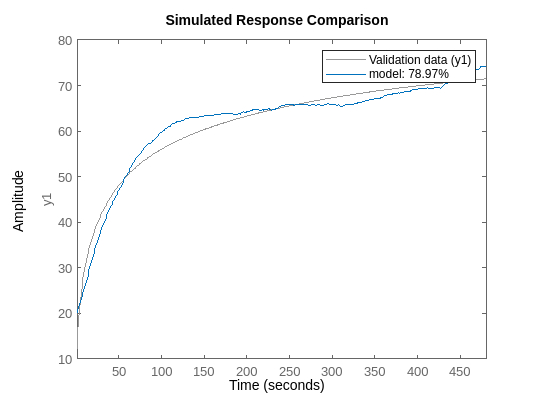

compare(sys,model);

## Simulation

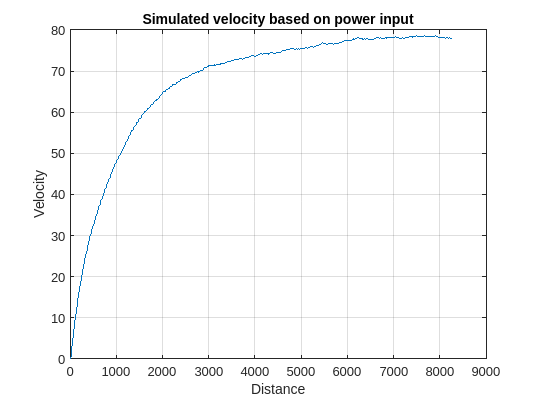

k = size(dist,1);

a = 0.829;
b = 1.15;
ScatterFactor = a + (b-a)*rand(k,1);

SimPowerMean =180;

simPower = ScatterFactor*SimPowerMean;
simSpeed = sim(model,simPower);

plot(dist, simSpeed);
title("Simulated velocity based on power input");
xlabel("Distance");
ylabel("Velocity");
grid on;